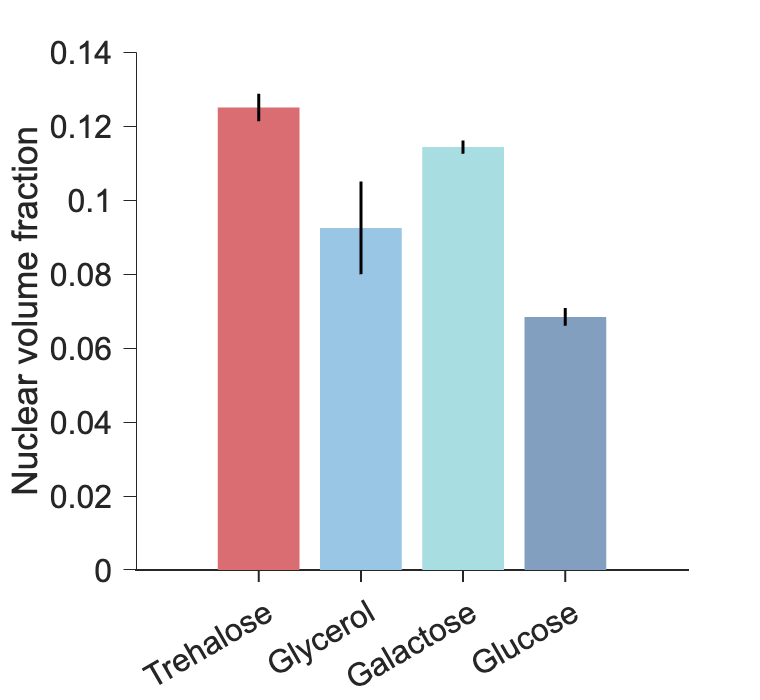

%% ========================================================================
%  mRNA production model — mass-action formulation
%  Purpose:
%    Predict mRNA concentration from RNAPII levels using a mass-action model.
%    The model links RNAPII binding (Kd fit from bound-fraction data) and
%    effective nuclear RNAPII/DNA/volume terms to mRNA output via a single
%    scale parameter (para_km).
%
%  Assumes:
%    - color_rgb.mat on path (color_rb, rgb_sort, etc.)
%    - growth&ribo data.mat on path (growth_rate, etc.)
%    - adjust_fig_nogrid.m on path (plot styling)
% ========================================================================

clc;
clear all;

% Measured mRNA fold-change (Trehalose, Glycerol, Galactose, Glucose; 4x1)
mRNA_measured     = [0.2394, 0.4663, 0.7006, 1]';      % spike-in normalized
%mRNA_measured   = [0.25, 0.5551, 0.6844, 1]';         % alt version (optional)
mRNA_measured_sem = [0.0159 0.0892 0.0300 0.0135]';    % SEM per condition

load('color_rgb.mat');  % loads color_rb colormap

% Nuclear volume fraction replicates (two replicates per condition; 4x2)
f_raw = [0.1287 0.1213;
         0.1050 0.0799;
         0.1125 0.1161;
         0.0708 0.0660];

% Summary statistics for nuclear volume fraction
f_mean = mean(f_raw, 2);           % mean per condition (4x1)
f_min  = min(f_raw, [], 2);
f_max  = max(f_raw, [], 2);
rangeL = f_mean - f_min;           % lower half-range for error bars
rangeU = f_max  - f_mean;          % upper half-range

% --- Plot: nuclear volume fraction with half-range error bars -------------
figure; hold on;
for i = 1:length(f_mean)
    bar(i, f_mean(i), 'FaceColor', color_rb(i,:), 'EdgeColor', 'none');
end
errorbar(1:length(f_mean), f_mean, rangeL, rangeU, ...
    'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 0);
xticks(1:length(f_mean));
xticklabels({'Trehalose','Glycerol','Galactose','Glucose'});
ylabel('Nuclear volume fraction');
adjust_fig_nogrid; legend off;
set(gcf,'position',[100 100 380 350])

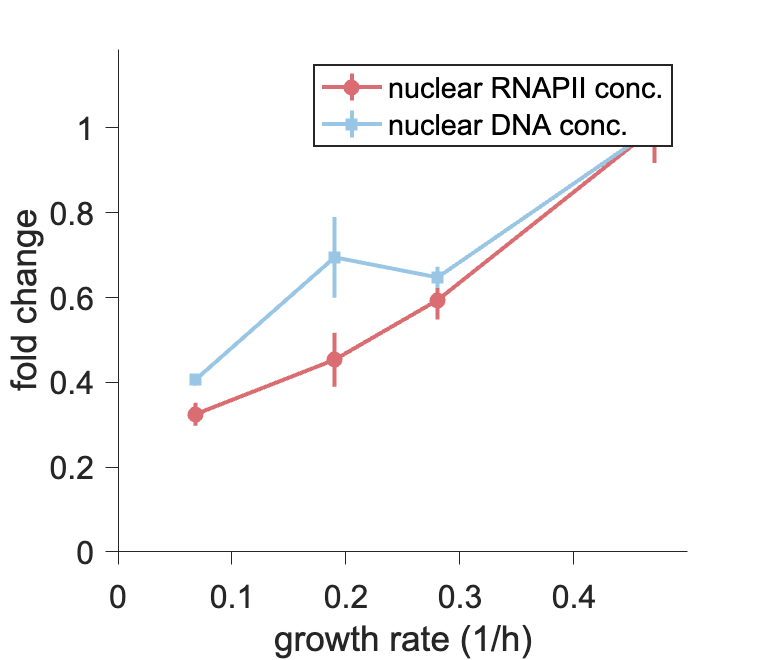


%% 1) Load growth rate & colormap for later plots
load('growth&ribo data.mat');    % provides growth_rate, etc.

% Growth rates arranged to match the 4 carbon sources (4x1)
% Order: Trehalose (12), Glycerol (6), Galactose (4), Glucose (5)
gr = [mean(growth_rate(12,:),2);
      mean(growth_rate(6,:), 2);
      mean(growth_rate(4,:), 2);
      mean(growth_rate(5,:), 2)];

% RNAP II proteome fraction (up to 3 reps each; NaN allowed)
RNAPII_fraction = [0.0013    0.0015       NaN;
                   0.0015    0.0014       NaN;
                   0.0019    0.0020       NaN;
                   0.0023    0.0021    0.0027];

% Total protein fraction P (two replicates per condition; 4x2)
P = [1.03,   0.9698;
     0.9961, 0.9961;
     1.2852, 1.1143;
     0.9882, 1.0039];

% SEM for nuclear fraction (from f_raw above)
f_mean = nanmean(f_raw,2);
f_sem  = nanstd(f_raw, 0, 2) ./ sqrt(sum(~isnan(f_raw), 2));

% RNAPII fraction summary (mean ± SEM across available reps)
RNAPII_fraction_mean = nanmean(RNAPII_fraction,2);
RNAPII_fraction_sem  = nanstd(RNAPII_fraction, 0, 2) ./ sqrt(sum(~isnan(RNAPII_fraction), 2));

% Protein fraction summary (mean ± SEM across two reps)
P_mean = mean(P, 2);
P_sem  = std(P, 0, 2) ./ sqrt(size(P,2));

% Nuclear/cytoplasm ratio summary vectors (renamed for clarity)
nuc_mean = f_mean(:);
nuc_sem  = f_sem(:);

% Effective nuclear RNAPII concentration scale:
% R ∝ (RNAPII proteome fraction) × (total protein fraction) / (nuclear fraction)
R_mean = RNAPII_fraction_mean .* P_mean ./ nuc_mean;

% Error propagation for R (assuming independence; linearized)
R_sem = R_mean .* sqrt( (RNAPII_fraction_sem ./ RNAPII_fraction_mean).^2 ...
                      + (P_sem ./ P_mean).^2 ...
                      + (nuc_sem ./ nuc_mean).^2 );

% Normalize by max to put conditions on 0–1 scale for visualization
mu_R     = max(R_mean);
R_norm   = R_mean ./ mu_R;
R_sem_norm = R_sem ./ mu_R;

% DNA content (two replicates per condition; 4x2)
DNA = [1.174,  1.190;
       1.5763, 1.5718;
       1.620,  1.5885;
       1.745,  1.7739];

% Cell volume (three replicates per condition; 4x3)
Vcell = [48.45, 46.64, 49.64;
         49.67, 50.02, 52.65;
         44.75, 42.36, 47.67;
         54.39, 53.09, 52.46];

% Summaries for DNA and Vcell with SEM
DNA_mean = mean(DNA, 2);
DNA_sem  = std(DNA, 0, 2) ./ sqrt(size(DNA,2));
V_mean   = mean(Vcell, 2);
V_sem    = std(Vcell, 0, 2) ./ sqrt(size(Vcell,2));

% Nuclear DNA concentration proxy: C ∝ DNA / (Vcell * nuclear fraction)
f_mean = f_mean(:);  % ensure column
f_sem  = f_sem(:);
C_mean = DNA_mean ./ (V_mean .* f_mean);

% Propagate SEM for C (ratio product rule)
C_sem = C_mean .* sqrt( ...
    (DNA_sem ./ DNA_mean).^2 + ...
    (V_sem   ./ V_mean  ).^2 + ...
    (f_sem   ./ f_mean  ).^2 );

% Normalize C to max = 1 for plotting alongside R_norm
scale  = max(C_mean);
C_mean = C_mean / scale;
C_sem  = C_sem  / scale;

% --- Plot: nuclear RNAPII conc. proxy vs nuclear DNA conc. proxy ----------
figure; hold on;
errorbar(gr, R_norm, R_sem_norm, 'o-', ...
    'Color',          color_rb(1,:), ...
    'MarkerFaceColor',color_rb(1,:), ...
    'MarkerEdgeColor',color_rb(1,:), ...
    'MarkerSize',     6, ...
    'LineWidth',      2, ...
    'CapSize',        0);
errorbar(gr, C_mean, C_sem, 's-', ...
    'Color',          color_rb(2,:), ...
    'MarkerFaceColor',color_rb(2,:), ...
    'MarkerEdgeColor',color_rb(2,:), ...
    'MarkerSize',     6, ...
    'LineWidth',      2, ...
    'CapSize',        0);
adjust_fig_nogrid;
axis([0 0.5 0 2*mean(R_norm)])
legend('nuclear RNAPII conc.','nuclear DNA conc.');
xlabel('growth rate (1/h)');
ylabel('fold change');

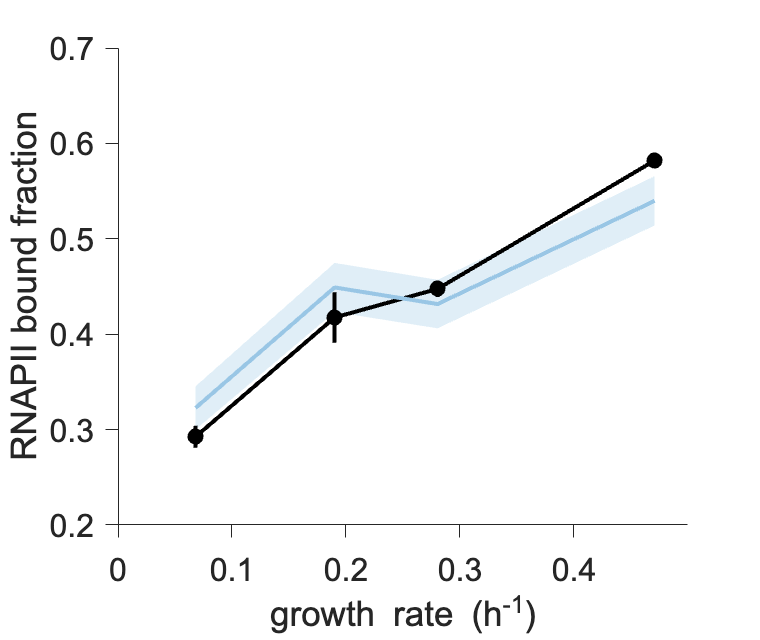

set(gcf,'position',[100 100 380 330])

%% ------------------------------------------------------------------------
%  Model: fit Kd from RNAPII bound fraction y = 1 / (1 + Kd * V * f / DNA)
%  Then, fit para_km from mRNA_measured using: mRNA = para_km * P*pol / (dm*(1+Kd*V*f/DNA))
%  This section computes Kd_best and para_km with 90% CI via fitnlm/predict.
% ------------------------------------------------------------------------

% % ---- Example parameter block (commented in your original) ---------------
% % pol_fraction = [0.0013 0.0015 0.0019 0.0023];
% % P = [1.0000 0.9961 1.1997 0.9961];
% % dm = [0.2906 0.2721 0.2764 0.3021];
% % f = [0.113 0.076 0.105 0.061];
% % DNA = [1.09 1.46 1.49 1.74];
% % Vcell = [48.24 50.78 44.93 53.31];
% % mRNA_measured = [0.243 0.564 0.636 1];
% % gr = [0.1015 0.1950 0.2802 0.4542];

% RNAPII bound fraction (two replicates × 4 conditions; 4x2)
bound_frac_measured = [0.281, 0.391, 0.439, 0.582;
                       0.304, 0.444, 0.456, 0.582]';  % (4x2) stored transposed

% Means for fitting/plotting (y_mean ± half-range)
Vbar      = mean(Vcell, 2);                % 4x1
DNAb      = mean(DNA,   2);                % 4x1
fbar      = f_mean;                        % 4x1 (from earlier)
y_mean    = mean(bound_frac_measured, 2);  % 4x1
err_range = range(bound_frac_measured, 2)/2;

% Flatten replicates to 8x1 for fitnlm; replicate predictors accordingly
y_data = bound_frac_measured(:);           % 8x1
X_base = [Vbar, fbar, DNAb];               % 4x3
X_data = repmat(X_base, 2, 1);             % 8x3

% Nonlinear model: y = 1 / (1 + Kd * V * f / DNA)
modelfun = @(b, X) 1 ./ (1 + b(1) .* X(:,1) .* X(:,2) ./ X(:,3));
beta0    = 1;  
mdl      = fitnlm(X_data, y_data, modelfun, beta0);

% Predict 90% CI at the 4 base points
[X_pred, yCI] = deal(X_base, []);  
[yPred, yCI]  = predict(mdl, X_pred, 'Prediction','curve', 'Alpha',0.10);

% --- Plot: RNAPII bound fraction (data vs model with CI) ------------------
figure; hold on;
x_fill = [gr; flipud(gr)];
y_fill = [yCI(:,1); flipud(yCI(:,2))];
fill(x_fill, y_fill, color_rb(2,:), 'FaceAlpha',0.3, 'EdgeColor','none');  % 90% CI band
errorbar(gr, y_mean, err_range, 'ko-', 'LineWidth',2, 'MarkerFaceColor','k', 'CapSize',0);
plot(gr, yPred, '-', 'LineWidth',2, 'Color',color_rb(2,:), 'MarkerSize',6);
xlabel('growth rate (h^{-1})'); ylabel('RNAPII bound fraction');
legend('', 'SMT data', 'Transcription model', 'Location','northwest');
axis([0, 0.5, 0.2, 0.7]); adjust_fig_nogrid;
set(gcf, 'Position', [100, 100, 380, 320]);


% Best-fit Kd
Kd_best = mdl.Coefficients.Estimate(1);

%% Fit para_km for mRNA: mRNA = para_km * [P * RNAPII_fraction] / [dm * (1 + Kd*V*f/DNA)]
% Use averaged inputs (Pbar, dmbar) and previously computed RNAPII_fraction_mean, Vbar, fbar, DNAb.
Pbar  = mean(P,  2);        % 4x1
dmbar = mean([0.3105,0.2937;
              0.2999,0.2528;
              0.2717,0.2724;
              0.3042,0.2771], 2);   % 4x1 (your provided dm replicates)

% Predictor X2 (4x1): everything except the global scale para_km
X2 = Pbar .* RNAPII_fraction_mean ./ ( dmbar .* (1 + Kd_best .* Vbar .* fbar ./ DNAb) );

% Linear-in-parameter fit: mRNA = para_km * X2
modelfun2 = @(b, X) b(1) .* X;
beta0_2   = 1;
mdl2      = fitnlm(X2, mRNA_measured, modelfun2, beta0_2);

% Best-fit para_km and 90% CI for mean response
parakm_best = mdl2.Coefficients.Estimate(1);
fprintf('Best-fit parakm = %.4f\n', parakm_best);

Best-fit parakm = 207.2181


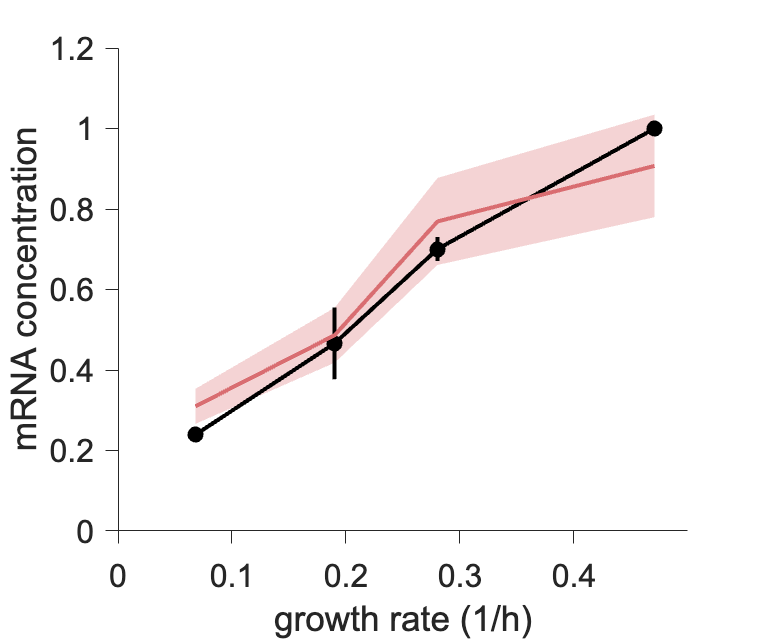

[yPred2, yCI2] = predict(mdl2, X2, 'Prediction','curve', 'Alpha',0.10);

% --- Plot: mRNA measured vs model with 90% CI -----------------------------
figure; hold on;
x_fill    = [gr; flipud(gr)];
y_lower   = yCI2(:,1);
y_upper   = yCI2(:,2);
y_fill    = [y_lower; flipud(y_upper)];
fill(x_fill, y_fill, color_rb(1,:), 'FaceAlpha',0.3, 'EdgeColor','none'); % 90% CI band

errorbar(gr, mRNA_measured, mRNA_measured_sem, 'ko-', ...
    'LineWidth',2, 'MarkerFaceColor','k', 'MarkerSize',6,'CapSize',0);

plot(gr, yPred2, '-', 'LineWidth',2, 'Color',color_rb(1,:), ...
     'MarkerFaceColor',color_rb(1,:), 'MarkerSize',6);

xlabel('growth rate (1/h)');
ylabel('mRNA concentration');
legend('','spike-in RNA-seq data','Transcription model','Location','best');
axis([0,0.5, min(yCI2(:,1))*0.9, max(yCI2(:,2))*1.1]);
adjust_fig_nogrid; axis([0 0.5 0 1.2]);
set(gcf,'Position',[100,100,380,320]);


%% ------------------------------------------------------------------------
% active RNAPII and mRNA (dual-axis plot template) — kept commented
% ------------------------------------------------------------------------
% figure; hold on;
% yyaxis left
% h1 = errorbar(gr_mean, cp_mean, cp_sem, 'o-', ...
%     'MarkerSize',8, 'MarkerFaceColor', color_rb(4,:), ...
%     'MarkerEdgeColor', color_rb(4,:), 'Color', color_rb(4,:), ...
%     'LineWidth',1.5, 'CapSize',0);
% ylim([0, 2*mean(cp_mean)]); ylabel('Active RNAPII in proteome');
% yyaxis right
% h2 = errorbar(gr_mean, mRNA_mean, mRNA_sem, 's--', ...
%     'MarkerSize',8, 'MarkerFaceColor', color_rb(1,:), ...
%     'MarkerEdgeColor', color_rb(1,:), 'Color', color_rb(1,:), ...
%     'LineWidth',1.5, 'CapSize',0);
% ylim([0, 2*mean(mRNA_mean)]); ylabel('mRNA measured');
% xlabel('growth rate (1/h)'); adjust_fig_nogrid;
% legend([h1,h2],{'active RNAPII','mRNA measured'},'Location','best');
% xlim([0 0.5]); set(gcf,'position',[100 100 450 330])
